data = load('resultadosCSV_magic.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

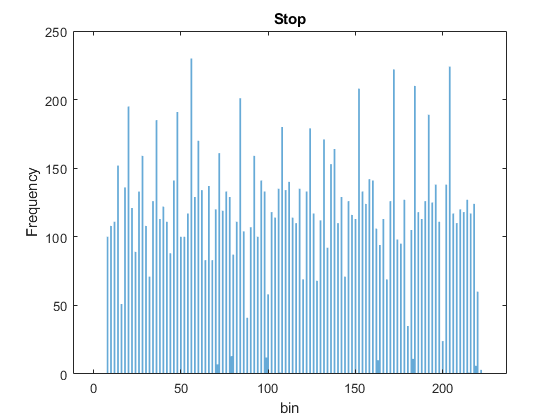

clf;
fig = figure;
bordes      = -0.5:1:225.5;
h1           = histogram(stop, bordes); title('Stop'); xlabel('bin'); ylabel('Frequency');
h1.EdgeColor = 'none';
bines_stop  = h1.BinCounts;
% saveas(gcf,'histograma_stop.eps', 'eps');
exportgraphics(fig,'histograma_stop.eps')

    
maxbin_stop = max(find(bines_stop, 1, 'last'))-1

maxbin_stop = 222

minbin_stop = min(find(bines_stop, 1, 'first'))-1

minbin_stop = 8

Nc_stop     = maxbin_stop - minbin_stop

Nc_stop = 214


T   = (1/300e6);
tau = T/Nc_stop

tau = 1.5576e-11

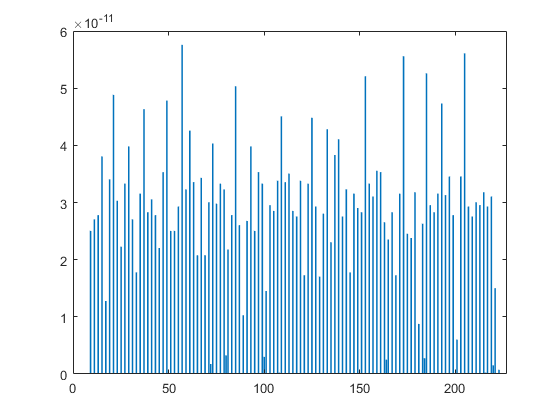

tau_stop = tau;

%%Real

N           = length(stop);    %numero de ensayos

ti_stop         = bines_stop*(T/N);
bar(ti_stop)

t = tiledlayout(3,1);

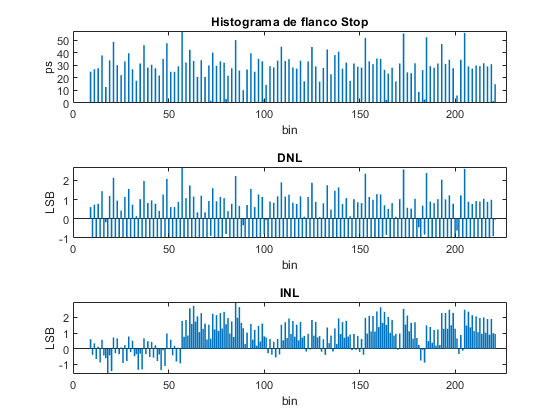

%Histograma
nexttile;

bar(ti_stop(1, 1:end)); ylabel('ps'); xlabel('bin'); title('Histograma de flanco Stop');
ax = gca; 
valoresY = ax.YAxis.TickValues;
% ax.YAxis.TickValuesMode = "manual";
yticks([0 10 20 30 40 50 60 70 80 90]*1e-12)
yticklabels({0 10 20 30 40 50 60 70 80 90})

%DNL
nexttile;
dnl_stop = (ti_stop - tau_stop)/tau_stop;
dnl_stop(1, 1:minbin_stop) = 0;
dnl_stop(1, maxbin_stop:end) = 0;
bar(dnl_stop(1, 1:end)); ylabel('LSB'); xlabel('bin'); title('DNL')

%INL
nexttile;
inl_stop = cumsum(dnl_stop);
inl_stop(1, maxbin_stop:end) = 0;
bar(inl_stop(1:end)); ylabel('LSB'); xlabel('bin'); title('INL')

exportgraphics(t,'linealidad_stop.eps')

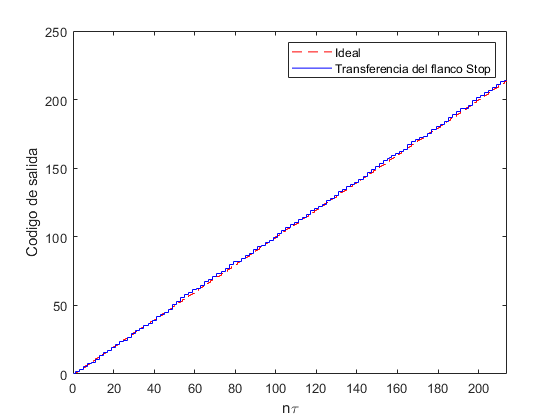

% saveas(gcf,'linealidad_stop.eps', 'eps');

clf;
% x_tiempo = 0:tau_stop:(tau_stop*Nc_stop);
format short
x_tiempo = 0:maxbin_stop-minbin_stop;
y_ideal  = 0:length(x_tiempo)-1;
y_real = inl_stop(1, minbin_stop:maxbin_stop) + y_ideal;
% plot(x_tiempo, y_ideal, x_tiempo, y_real);
stairs(x_tiempo, y_ideal, 'r--');
hold on;
stairs(x_tiempo, y_real, 'b')
hold off;
xlabel('n\tau'); ylabel('Codigo de salida');
legend('Ideal', 'Transferencia del flanco Stop');
ax = gca; 
ax.XLim = [0, max(x_tiempo)];
% saveas(gcf,'transferencia_stop.eps', 'eps');
exportgraphics(gcf,'transferencia_stop.eps')

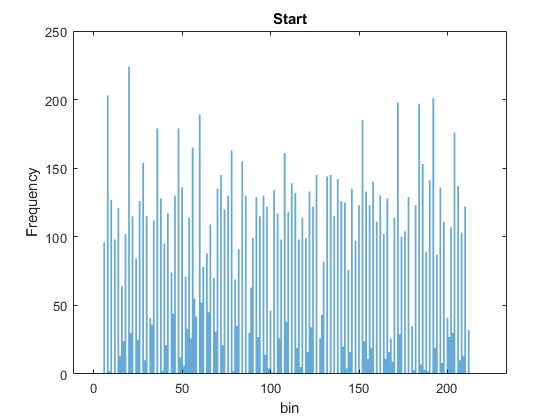

clf;
fig = figure();
bordes      = -0.5:1:222.5;
h           = histogram(start, bordes); title('Start'); xlabel('bin'); ylabel('Frequency');
h.EdgeColor = 'none';
bines_start = h.BinCounts;
exportgraphics(fig,'histograma_start.eps');

% export_fig('prueba','-eps', '-r600');
    
maxbin_start = max(find(bines_start, 1, 'last'))

maxbin_start = 213

minbin_start = min(find(bines_start, 1, 'first'))

minbin_start = 7

Nc_start     = maxbin_start - minbin_start

Nc_start = 206


%%Ideal
T   = (1/300e6);
tau_start = T/Nc_start

tau_start = 1.6181e-11


%%Real
clf;
N           = length(start);    %numero de ensayos

t_start = tiledlayout(3,1)

t_start =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


%Histograma
nexttile;
ti_start         = bines_start*(T/N);
bar(ti_start(1, 1:end)); ylabel('ps'); xlabel('bin'); title('Histograma de flanco Start')
ax = gca; 
valoresY = ax.YAxis.TickValues;
% ax.YAxis.TickValuesMode = "manual";
yticks([0 10 20 30 40 50 60 70]*1e-12)
yticklabels({0 10 20 30 40 50 60 70})

%DNL
nexttile;
dnl_start = (ti_start - tau_start)/tau_start;
dnl_start(1, 1:minbin_start) = 0;
dnl_start(1, maxbin_start:end) = 0;
bar(dnl_start(1, 1:end)); ylabel('LSB'); xlabel('bin'); title('DNL')

%INL
nexttile;
inl_start = cumsum(dnl_start)

inl_start =          0         0         0         0         0         0         0   -1.0000    1.1414    0.1723    1.1376    0.1376    0.6541   -0.3459    0.5266   -0.2722   -0.2819   -0.9105   -0.3320   -1.3320    1.1343    0.5986    1.3782    0.3782    0.6780    0.0649    1.0147    0.0147    1.3978    0.5526    1.3322    0.3322   -0.0334   -0.4763    0.2569   -0.7431    1.0269    0.0269    1.0077    0.0386    0.5087   -0.1663    0.6442   -0.3558   -0.2106   -0.5297    0.4820   -0.5180    1.2520    0.4377


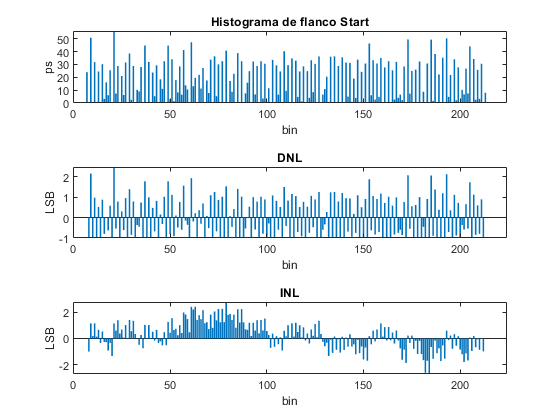

inl_start(1, maxbin_start:end) = 0;
bar(inl_start(1:end)); ylabel('LSB'); xlabel('bin'); title('INL')

exportgraphics(t_start,'linealidad_start.eps');

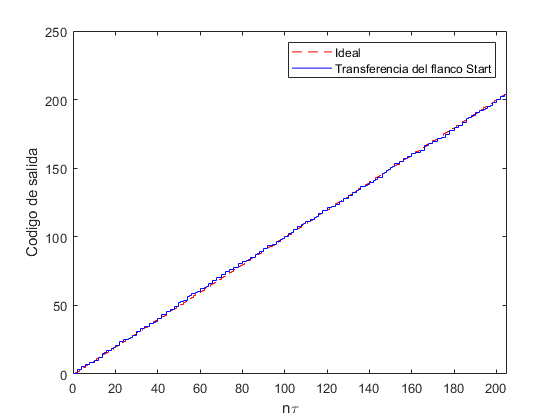


clf;
% x_tiempo = 0:tau_stop:(tau_stop*Nc_stop);
format short
x_tiempo = 0:Nc_start-1;
y_ideal  = 0:length(x_tiempo)-1;
y_real = inl_start(1, minbin_start:maxbin_start-1)+y_ideal;
% plot(x_tiempo, y_ideal, x_tiempo, y_real);
stairs(x_tiempo, y_ideal, 'r--');
hold on;
stairs(x_tiempo, y_real, 'b')
hold off;
xlabel('n\tau'); ylabel('Codigo de salida');
legend('Ideal', 'Transferencia del flanco Start');
ax = gca; 
ax.XLim = [0, max(x_tiempo)];
exportgraphics(gcf,'transferencia_start.eps');

# Calibración

clf;

ti_start

ti_start = 	1.0e+-10 *

         0         0         0         0         0         0    0.2404         0    0.5083    0.0050    0.3180         0    0.2454         0    0.3030    0.0326    0.1603    0.0601    0.2554         0    0.5609    0.0751    0.2880         0    0.2103    0.0626    0.3155         0    0.3856    0.0250    0.2880         0    0.1027    0.0901    0.2804         0    0.4482         0    0.3205    0.0050    0.2379    0.0526    0.2930         0    0.1853    0.1102    0.3255         0    0.4482    0.0300


minbin_start

minbin_start = 7

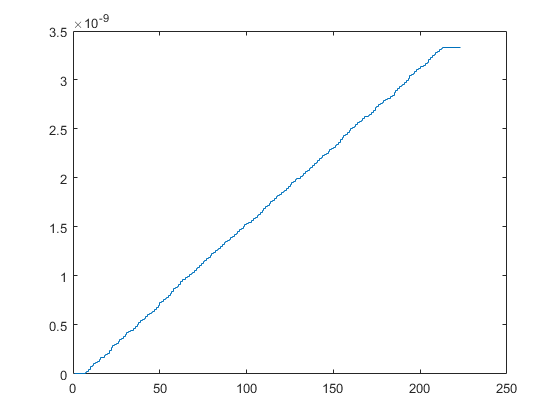

cumsum_start = cumsum([0, ti_start]);
cal_start =   cumsum_start(1:end-1) + ti_start/2;
stairs(cal_start);

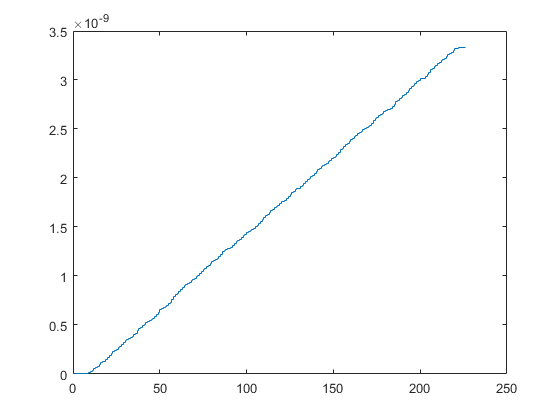


cumsum_stop = cumsum([0, ti_stop]);
cal_stop =   cumsum_stop(1:end-1) + ti_stop/2;
stairs(cal_stop);


minbin_start * tau_start - minbin_stop * tau_stop

ans = -1.1342e-11

%GUARDAR CALIBRACION!
save('DatosCalibracion.mat', 'tau', 'maxbin_start', 'minbin_start', 'maxbin_stop', 'minbin_stop', 'tau_start', 'tau_stop', 'cal_stop', 'cal_start');